# Projection on polytopes

buffer_train = struct with fields:
    X: [14×10000 double]
    Y: [3×10000 double]

buffer_validation = struct with fields:
    X: [14×1000 double]
    Y: [3×1000 double]

Nsamples = 11000

Ninputs = 14

Noutputs = 3

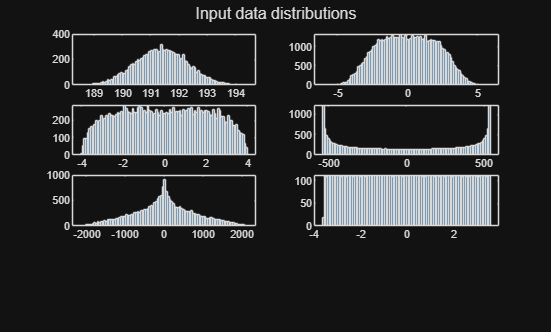

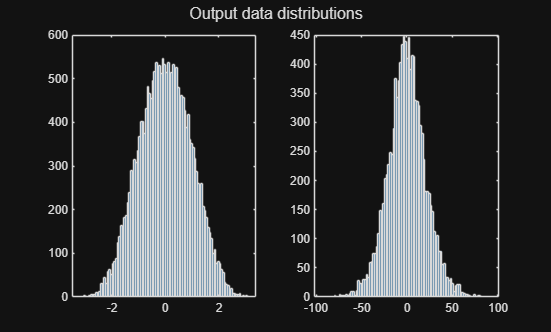

ans = 466.5614

ie_max = 3.1513

ix_max = 3.5800

iy_max = 4

is_max = 8.5000

vo_max = 415.1344

vB_max = 830.2687

VCdiff = 0.0100

eta = 1.7214

Xmax = 1.0e+03 *

    0.1914
    0.0038
    0.0038
    0.0038
    0.0038
    0.0038
    0.0038
    0.0040
    0.0040
    0.5374
    0.5374
    2.1496
    2.1496
    0.0036


Ymax =     8.5000
    8.5000
  415.1344


ans =           14       11000


ans =            3       11000


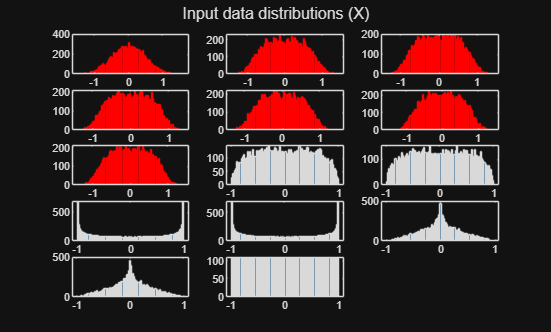

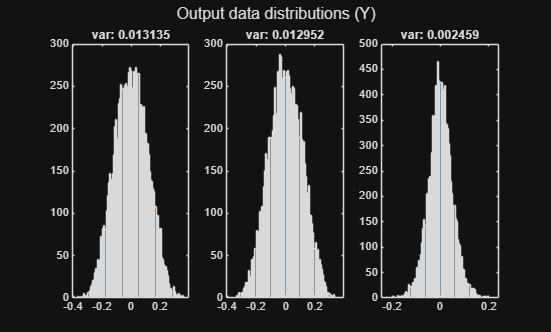

run('DataPreparation.mlx');

IS0 = load('ImitationLearning\TrainingData\Data\init_validation.mat').buffer_init.IS0;

# Data

function [is, ixy, iB, iz, ie] = generate_data(is, A, pinvA, pinvN)
    ixy = A * is;
    iB  = pinvA * ixy;
    iz  = is - iB;
    iz = 2 * iz; % Force constraint violation
    ie  = pinvN * iz;
    is  = iB + iz;
end

idx = 1;
[is, ixy, iB, iz, ie] = generate_data(IS0(:, idx), A, pinvA, pinvN)

is =     8.0707
   -0.0443
   -4.9871
  -11.9924
    2.3142
    6.6388


ixy =     3.0394
   -3.0394
    3.9217
   -2.2699
   -1.6518


iB =    -0.9477
    2.1481
    1.8390
   -2.9740
    0.1218
   -0.1873


iz =     9.0184
   -2.1924
   -6.8261
   -9.0184
    2.1924
    6.8261


ie =     2.1924
    6.8261



original = struct();
original.is  = is;
original.ixy = ixy;
original.iB  = iB;
original.iz  = iz;
original.ie  = ie;

function benchmark(ie_proj, time, Niter, original, optimal_projection, name, A, N, Ac, bc)
    iz_proj = N * ie_proj;
    is_proj = original.iB + iz_proj;
    ixy_proj = A * is_proj;
    
    projection = struct();
    projection.ie = ie_proj;
    projection.iz = iz_proj;
    projection.is = is_proj;
    projection.ixy = ixy_proj;

    disp('============================================================')
    disp(strcat(['Comparation of projection method: ', name]))
    disp('  Original | Optimal | Actual')

    disp('is')
    disp([original.is, optimal_projection.is, projection.is]);
    % disp('ixy')
    % disp([original.ixy, optimal_projection.ixy, projection.ixy]);
    % disp('iB')
    % disp([original.iB, optimal_projection.iB, projection.iB]);
    % disp('iz')
    % disp([original.iz, optimal_projection.iz, projection.iz]);
    disp('ie')
    disp([original.ie, optimal_projection.ie, projection.ie]);
    
    disp(' ')
    fprintf('Time: %d\n', time)
    fprintf('Iterations: %d\n', Niter)
    fprintf('Original max constraint violation: %d\n', max(Ac * original.ie - bc))
    fprintf('Projection max constraint violation: %d\n', max(Ac * ie_proj - bc))
    disp('============================================================')
end

# Constraints


$$-\check{i_s}\leq i_B+N\cdot i_\varepsilon\leq\hat{i_s}$$


Define matrices


$$A_c\cdot i_\varepsilon\leq b_c$$


Ac = [N; -N];
bc = [is_max - iB; is_max + iB];
pinvAc = pinv(Ac);

Polytope properties

analyzePolytope(Ac, bc);


=== Polytope Properties ===
Affine dimension     : 2
Bounded              : Yes
Number of facets     : 6
Number of vertices   : 6
Number of edges      : 6
Area                 : 144.6
Centroid             : [ 0 2.961e-16 ]
Chebyshev center     : [ -1.728 0.7149 ]
Inradius             : 4.624
Diameter             : 21.27



Visualize slice

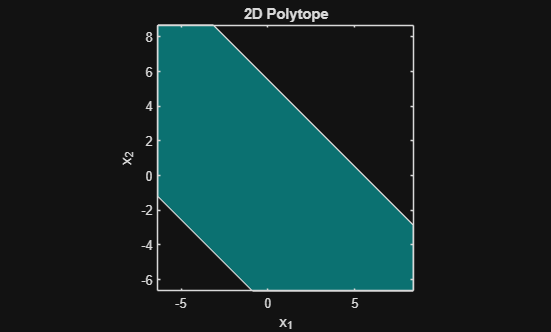

freeDim = 4;
visualizePolytope(Ac, bc, freeDim);

## Projector

Specifications

specsProjector = struct();

specsProjector.Ac      = Ac;
specsProjector.MaxIter = 100;
specsProjector.lambda  = 1;
specsProjector.Tol     = 1e-3;
specsProjector.Nx      = n;

## Quadratic programming solver

Create object

specsProjector.Method  = 'solver-qp';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

optimal_projection = struct();
optimal_projection.ie = ie_proj;
optimal_projection.iz = iz_proj;
optimal_projection.is = is_proj;
optimal_projection.ixy = ixy_proj;

fprintf('Time: %d\n', time)

Time: 6.178800e-03


fprintf('Iterations: %d\n', Niter)

Iterations: 2


fprintf('Original max constraint violation: %d', max(Ac * original.ie - bc))

Original max constraint violation: 3.492407e+00

fprintf('Projection max constraint violation: %d', max(Ac * ie_proj - bc))

Projection max constraint violation: -8.881784e-16

## Scalar clipping

Create object

specsProjector.Method  = 'scalar-clipping';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: scalar-clipping
  Original | Optimal | Actual
is
    8.0707    4.5783    4.5783
   -0.0443    1.7019    0.8047
   -4.9871   -3.2408   -2.3436
  -11.9924   -8.5000   -8.5000
    2.3142    0.5680    1.4652
    6.6388    4.8926    3.9954
ie
    2.1924    0.4462    1.3434
    6.8261    5.0799    4.1827
 
Time: 5.640000e-04
Iterations: 1
Original max constraint violation: 3.492407e+00
Projection max constraint violation: 0


## Cimmino original

Mean of constraint violations

Create object

specsProjector.Method  = 'cimmino-original';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: cimmino-original
  Original | Optimal | Actual
is
    8.0707    4.5783    4.5793
   -0.0443    1.7019    1.7015
   -4.9871   -3.2408   -3.2413
  -11.9924   -8.5000   -8.5010
    2.3142    0.5680    0.5685
    6.6388    4.8926    4.8931
ie
    2.1924    0.4462    0.4466
    6.8261    5.0799    5.0803
 
Time: 3.704400e-03
Iterations: 94
Original max constraint violation: 3.492407e+00
Projection max constraint violation: 9.794903e-04


## Cimmino greedy

Max of constraint violations

Create object

specsProjector.Method  = 'cimmino-greedy';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: cimmino-greedy
  Original | Optimal | Actual
is
    8.0707    4.5783    4.5783
   -0.0443    1.7019    1.7019
   -4.9871   -3.2408   -3.2408
  -11.9924   -8.5000   -8.5000
    2.3142    0.5680    0.5680
    6.6388    4.8926    4.8926
ie
    2.1924    0.4462    0.4462
    6.8261    5.0799    5.0799
 
Time: 1.010700e-03
Iterations: 1
Original max constraint violation: 3.492407e+00
Projection max constraint violation: -8.881784e-16


## Dykstra

Create object

specsProjector.Method  = 'dykstra';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: dykstra
  Original | Optimal | Actual
is
    8.0707    4.5783    4.5783
   -0.0443    1.7019    1.7019
   -4.9871   -3.2408   -3.2408
  -11.9924   -8.5000   -8.5000
    2.3142    0.5680    0.5680
    6.6388    4.8926    4.8926
ie
    2.1924    0.4462    0.4462
    6.8261    5.0799    5.0799
 
Time: 4.472100e-03
Iterations: 1
Original max constraint violation: 3.492407e+00
Projection max constraint violation: -8.881784e-16


## Douglas Rachford

Create object

specsProjector.Method  = 'douglas-rachford';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: douglas-rachford
  Original | Optimal | Actual
is
    8.0707    4.5783    4.5783
   -0.0443    1.7019    1.7019
   -4.9871   -3.2408   -3.2408
  -11.9924   -8.5000   -8.5000
    2.3142    0.5680    0.5680
    6.6388    4.8926    4.8926
ie
    2.1924    0.4462    0.4462
    6.8261    5.0799    5.0799
 
Time: 3.221900e-03
Iterations: 1
Original max constraint violation: 3.492407e+00
Projection max constraint violation: -8.881784e-16


## Peaceman Rachford

Create object

specsProjector.Method = 'peaceman-rachford';
specsProjector.lambda = 0.5;
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: peaceman-rachford
  Original | Optimal | Actual
is
    8.0707    4.5783    4.5783
   -0.0443    1.7019    1.7019
   -4.9871   -3.2408   -3.2408
  -11.9924   -8.5000   -8.5000
    2.3142    0.5680    0.5680
    6.6388    4.8926    4.8926
ie
    2.1924    0.4462    0.4462
    6.8261    5.0799    5.0799
 
Time: 3.220900e-03
Iterations: 1
Original max constraint violation: 3.492407e+00
Projection max constraint violation: -8.881784e-16


Projection layer

% layers = layerGraph(net);
% concatLayer = concatenationLayer(1, 2, 'Name', 'concat');
% projLayer = HardNetProjection('cimmino_max', M3C.A, M3C.N, M3C.C, is_max, Xmax, Ymax, 'projection');
% layers = addLayers(layers, concatLayer);
% layers = addLayers(layers, projLayer);
% layers = connectLayers(layers, net.Layers(end).Name, 'concat/in1');
% layers = connectLayers(layers, net.InputNames{1}, 'concat/in2');
% layers = connectLayers(layers, 'concat', 'projection');
% net = dlnetwork(layers);
% 
% plot(net)